# 线性代数应用实例：PageRank 算法

[PageRank](http://en.wikipedia.org/wiki/PageRank) 网页排名, 又称网页级别, 是一种由搜索引擎根据网页之间相互的超链计算网页级别的技术。其核心思想如下图：

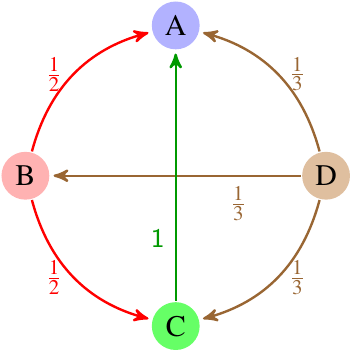


$$R(A)=\frac{1-d}{N} +d\Big( \frac{R(B)}{2} + \frac{R(C)}{1} + \frac{R(D)}{3}\Big)$$


令$\mathbf{R}=(R_a,\, R_b,\, R_c,\, R_d)$，因此可列出线性方程

$\left\lbrack \begin{array}{c}
R_a \\
R_b \\
R_c \\
R_d 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\frac{1-d}{N}\\
\frac{1-d}{N}\\
\frac{1-d}{N}\\
\frac{1-d}{N}
\end{array}\right\rbrack +d\left\lbrack \begin{array}{cccc}
0 & \frac{1}{2} & \frac{1}{1} & \frac{1}{3}\\
0 & 0 & 0 & \frac{1}{3}\\
0 & \frac{1}{2} & 0 & \frac{1}{3}\\
0 & 0 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
R_a \\
R_b \\
R_c \\
R_d 
\end{array}\right\rbrack$　或　$\mathbf{R}=\mathbf{C}+d\;\mathbf{LR}$

因此有$\left(\mathbf{I}-d\;\mathit{\mathbf{L}}\right)\mathbf{R}=\mathbf{C}$, 因此解为 $\mathbf{R}={\left(\mathbf{I}-d\;\mathbf{L}\right)}^{-1} \mathbf{C}$

I = eye(4);
L = [0  1/2  1/1  1/3
     0   0    0   1/3
     0  1/2   0   1/3
     0   0    0    0 ];
 C = (1-0.85)/4 * ones(4,1);
 
 R = (I-0.85*L)\C

R =     0.1269
    0.0481
    0.0686
    0.0375


一个更一般的例子: 名人社交网络为例, 计算每个名人主页的 PageRank 值. 名人主页的 PageRank 值可以反映该名人的影响力. 图中的每条弧表示, 弧尾的名人关注了弧头的名人. 比如 Ellen 有一条弧指向 Bill, 表示 Ellen 关注了 Bill.

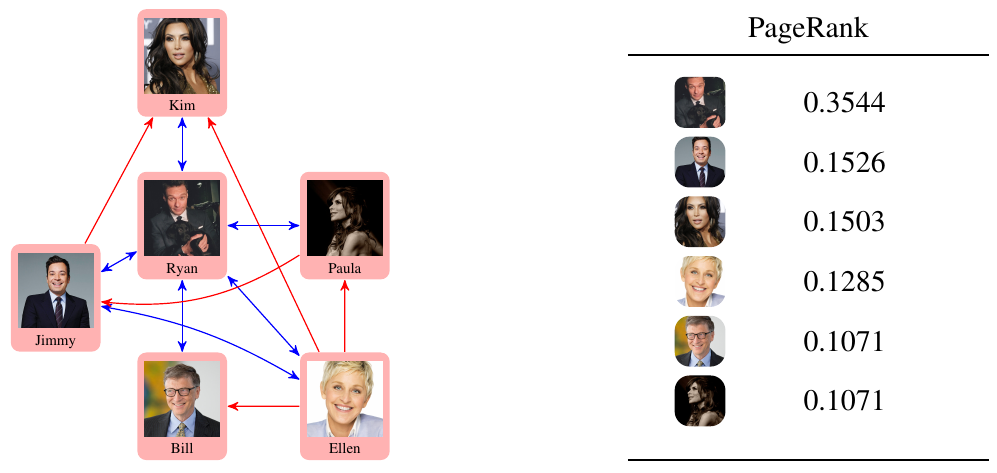

首先构建网络

name = {'bill', 'ellen', 'jimmy', 'kim', 'paula', 'ryan'}; % celebrities
[bil, ell, jim, kim, pau, rya] = deal(1,2,3,4,5,6);        % id

n = length(name); % number of celebrities

L = zeros(n);
% if user j follows user i, then L(i,j) = 1
L(bil, [rya, ell]) = 1;
L(jim, [rya, pau, ell]) = 1;
L(kim, [jim, rya, ell]) = 1;
L(pau, [rya, ell])=1;
L(rya, [bil, jim, kim, pau, ell]) = 1;
L(ell, [jim, rya]) = 1

L =      0     1     0     0     0     1
     0     0     1     0     0     1
     0     1     0     0     1     1
     0     1     1     0     0     1
     0     1     0     0     0     1
     1     1     1     1     1     0


根据网络计算$\mathbf{L}$矩阵

ot = sum(L,1);  % out-degree
L = L./ot

L =          0    0.2000         0         0         0    0.2000
         0         0    0.3333         0         0    0.2000
         0    0.2000         0         0    0.5000    0.2000
         0    0.2000    0.3333         0         0    0.2000
         0    0.2000         0         0         0    0.2000
    1.0000    0.2000    0.3333    1.0000    0.5000         0


 求解线性方程组

d = 0.86;  % damping factor
C = (1-d)/n*ones(n,1);
I = eye(n);
R = (I - d*L)\C

R =     0.1066
    0.1282
    0.1524
    0.1503
    0.1066
    0.3558
